# **drawVDim**

Draw vertical dimension

## Description

Vertical dimension measures  the vertical distance between two points.

## Syntax

drawVDim(form,d1,d2,x1,y1,x2,y2,xt,yt)

drawVDim(__,'-str',str)

drawVDim(_,LineSpec)

### Description

drawVDim(form,d1,d2,x1,y1,x2,y2,xt,yt) draw horizontal dimension between points (x1,y1) and (x2,y2) and locate text, i.e. value of distnce y2-y1, at point (xt,yt). If y2 < y1 than the points are swaped.

drawVDim(__,'-str',str) draw horizontal dimension between points (x1,y1) and (x2,y2) and locate text given by variable str at point (xt,yt).

drawVDim(__,LineSpec)  sets the line style, line width, and color.

### Method

drawVDim use drawLine, drawArrohwhead, and gkText to draw a vertical dimension . For drawing text the function drawVDim use current text attrubtes. They can be changed by function drawSet.

## Arguments

### Input Arguments

**form **- arrowhead form

**d1,d2 **- arrow head width and height

**x1,y1 **- start point. y1 colud be > y2

**x2,y2 **- end point

**xt,yt    **- text location. If xt is inside interval (x1,x2) then text is located at the center of the interval

### Optional Name-Value Pair Input Arguments

**'-str'|'-txt',str** - dimension text

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

## Examples

### Example 1

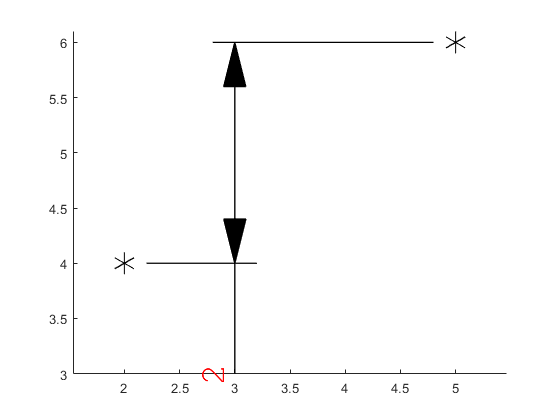

drawInit
ad1 = 0.4; ad2 = ad1/2;
x1 = 2; y1 = 4;
x2 = 5; y2 = 6;
xt = 3; yt = 3;
gkSet('FontSize',26)
drawPoint(1,ad1/2,x1,y1)
drawPoint(1,ad1/2,x2,y2)
drawVDim(3,ad1,ad2,x1,y1,x2,y2,xt,yt)

%grid on

### Example 2

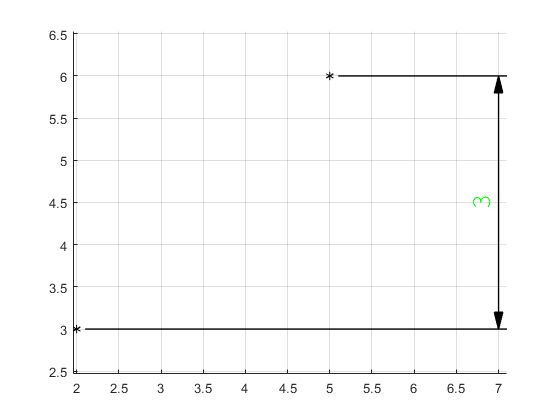

drawInit
ad1 = 0.2; ad2 = ad1/2;
x1 = 2; y1 = 3;
x2 = 5; y2 = 6;
xt = 7; yt = 4;
drawSet('FontSize',20,'textColor','g')
drawPoint(1,ad1/2,x1,y1)
drawPoint(1,ad1/2,x2,y2)
drawVDim(3,ad1,ad2,x1,y1,x2,y2,xt,yt)
grid on

### Example 3

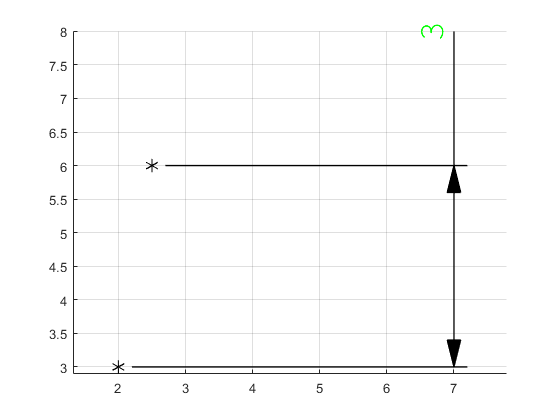

drawInit
ad1 = 0.4; ad2 = ad1/2;
x1 = 2; y1 = 3;
x2 = 2.5; y2 = 6;
xt = 7; yt = 8;
drawSet('FontSize',26)
drawPoint(1,ad1/2,x1,y1)
drawPoint(1,ad1/2,x2,y2)
drawVDim(3,ad1,ad2,x1,y1,x2,y2,xt,yt)
grid on

### Example 4

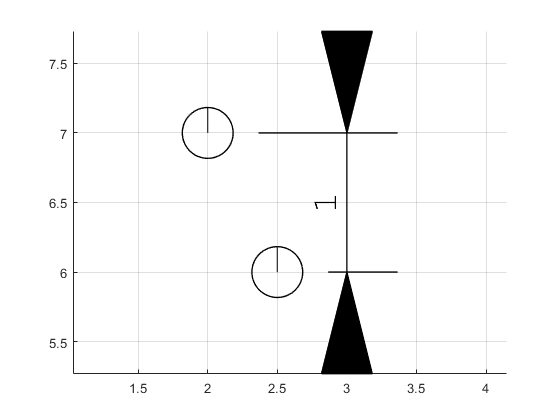

drawInit
ad1 = 0.73; ad2 = ad1/2;
x1 = 2; y1 = 7;
x2 = 2.5; y2 = 6;
xt = 3; yt = 7;
drawSet('FontSize',26)
drawPoint(3,ad2,x1,y1)
drawPoint(3,ad2,x2,y2)
drawVDim(3,ad1,ad2,x1,y1,x2,y2,xt,yt)
grid on

### Example 5

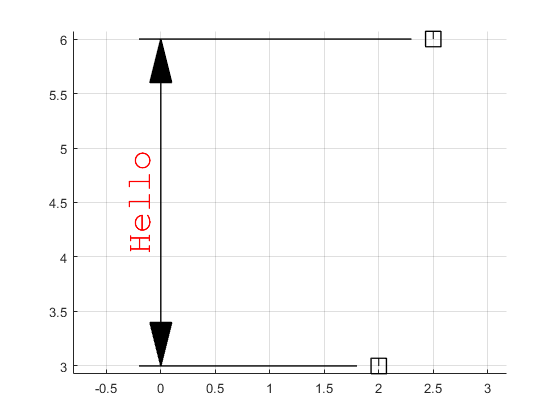

drawInit
ad1 = 0.4; ad2 = ad1/2;
x1 = 2; y1 = 3;
x2 = 2.5; y2 = 6;
xt = 0; yt = 4;
drawSet('FontSize',26,'textColor','r')
drawPoint(2,ad1/2,x1,y1)
drawPoint(2,ad1/2,x2,y2)
drawVDim(3,ad1,ad2,x1,y1,x2,y2,xt,yt,'-str','Hello')
grid on

### Example 6

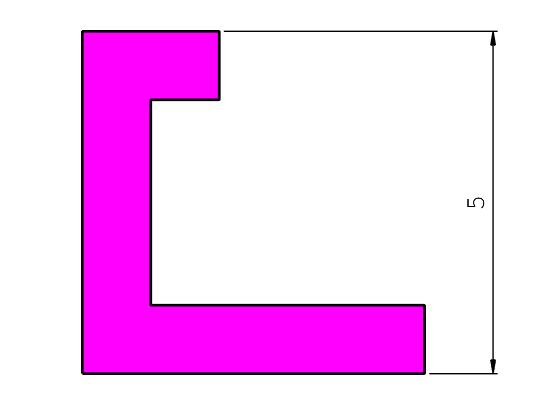

drawInit
ad1 = 0.2; ad2 = ad1/3;
a = 5; b = 3; c = 5; d = 1;
p = drawPolygon([0 a a d d   b-d b-d 0],...
                [0 0 d d c-d c-d c   c ],'LineWidth',2,'Color','k','-fill','m');
drawSet('FontSize',20,'textColor','k')
drawVDim(3,ad1,ad2,p.xk(2),p.yk(2),p.xk(7),p.yk(7),a*1.2,c)
axis off

## See also

## References